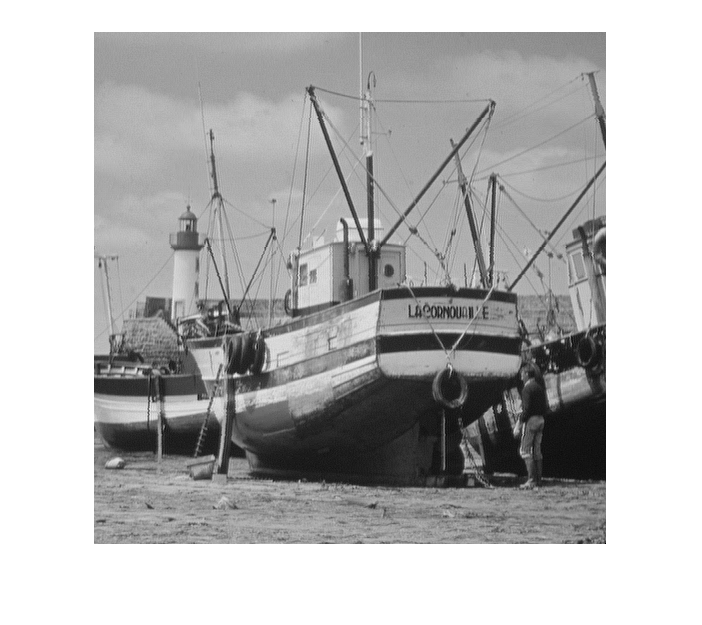

A=imread("C:\Users\Liushoukang\Desktop\VMIE\image\Lena256.bmp");
I=imread("C:\Users\Liushoukang\Desktop\VMIE\image\Boat512.bmp");
A=double(A);
[B0,B1,B2,B3]=IWT(I);
B1=B1+512;
B2=B2+512;
B3=B3+512;

B11 = floor(abs(B1)/2^3)*2^3+floor(A/2^5);

B11  = TK2(B11,B1,3);
        
B22 = floor(abs(B2)/2^3)*2^3+mod(floor(A/2^2),2^3);
B22 = TK2(B22,B2,3);
        
B33 = floor(abs(B3)/2^2)*2^2+mod(A,2^2);
B33 = TK2(B33,B3,2);

B11=B11-512;
B22=B22-512;
B33=B33-512;

ANS=mod(IIWT(B0,B11,B22,B33),256);
h=imshow(uint8(ANS));



psnr(uint8(ANS),I)

ans = 43.1187


[B0,B1,B2,B3]=IWT(ANS);
delta1=SUM(B11-B1)

delta1 = 0

delta2=SUM(B22-B2)

delta2 = 0

delta3=SUM(B33-B3)

delta3 = 0

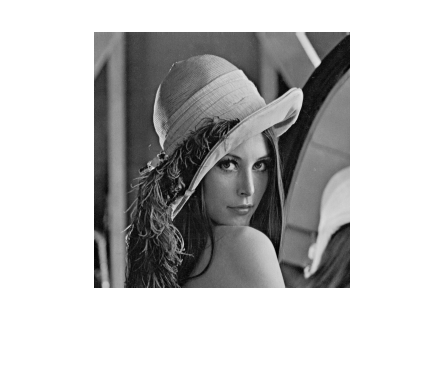


B1=B1+512;
B2=B2+512;
B3=B3+512;

A1=mod(abs(B1),2^3)*2^5+mod(abs(B2),2^3)*2^2+mod(abs(B3),2^2);
imshow(uint8(A1))

ssim(uint8(A1),uint8(A))

ans = 1

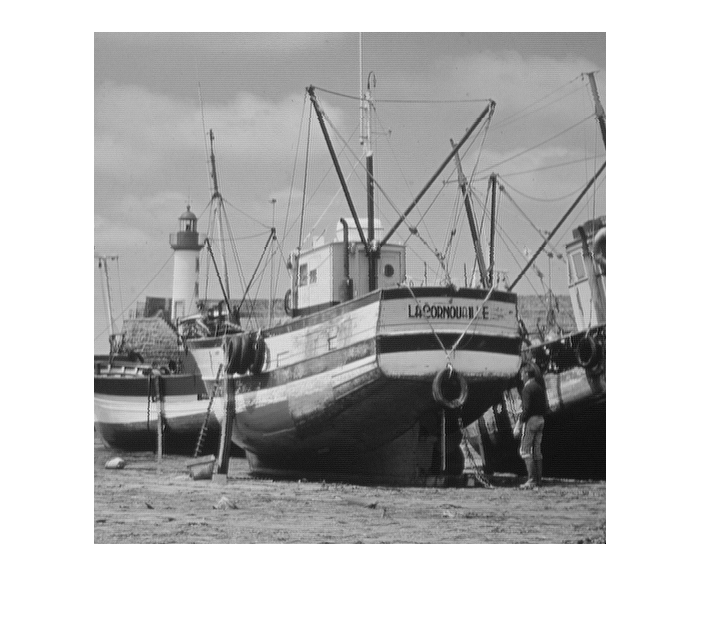

% 三平面嵌入法
[B0,B1,B2,B3]=IWT(I);
B11=floor(A./10^2)+B1;
B22=mod(floor(A./10),10)+B2;
B33=mod(A,10)+B3;
ANS=mod(IIWT(B0,B11,B22,B33),256);
imshow(uint8(ANS))

psnr(uint8(ANS),I)

ans = 38.6805

[Bt0,Bt1,Bt2,Bt3]=IWT(ANS);

A1=(Bt1-B1)*10^2+(Bt2-B2)*10+Bt3-B3;
imshow(uint8(A1))

ssim(uint8(A1),uint8(A))

ans = 1

% LBP纹理排序嵌入法2K校正比特1,2,2,3
[B0,B1,B2,B3]=IWT(I);
[M,N]=size(B0);

B1=B1+512;
B2=B2+512;
B3=B3+512;

% SUM(LBP(B0,30))
% SUM(LBP(B1,30))
% SUM(LBP(B2,30))
% SUM(LBP(B3,30))

B00=floor(A./2^7)+floor(abs(B0)/2)*2;
B00  = TK2(B00,B0,1);

SigB1=(B1>=0)+(B1<0)*-1;B1=abs(B1);
B11=mod(floor(A./2^5),2^2)+floor(B1/2^2)*2^2;
B11  = TK2(B11,B1,2);
B11  = SigB1.*B11;

SigB2=(B2>=0)+(B2<0)*-1;B2=abs(B2);
B22=mod(floor(A./2^3),2^2)+floor(B2/2^2)*2^2;
B22  = TK2(B22,B2,2);
B22  = SigB2.*B22;

SigB3=(B3>=0)+(B3<0)*-1;B3=abs(B3);
B33=mod(A,2^3)+floor(B3/2^3)*2^3;
B33  = TK2(B33,B3,3);
B33  = SigB3.*B33;


B11=B11-512;
B22=B22-512;
B33=B33-512;

ANS=IIWT(B00,B11,B22,B33);
MAX(ANS)

ans = 240

MIN(ANS)

ans = -3

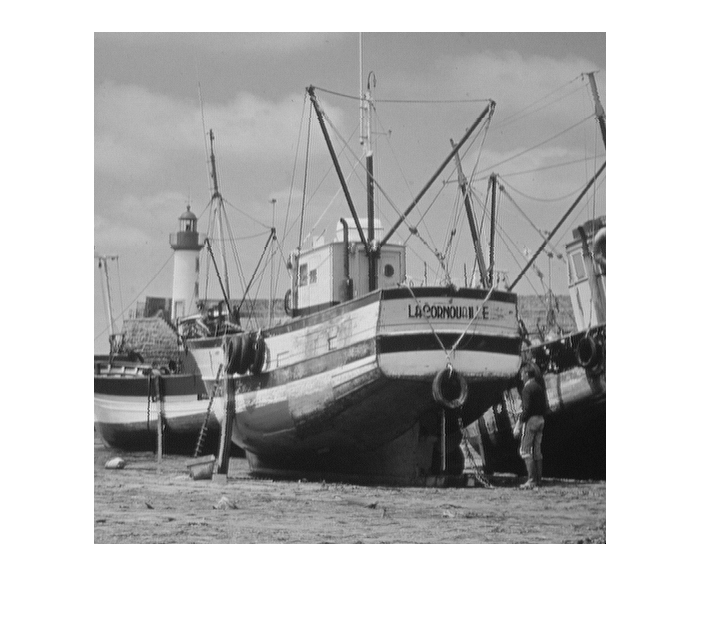

imshow(uint8(ANS))

psnr(uint8(ANS),I)

ans = 45.4442


[Bt0,Bt1,Bt2,Bt3]=IWT(ANS);
delta0=SUM(B00-Bt0)

delta0 = 0

delta1=SUM(B11-Bt1)

delta1 = 0

delta2=SUM(B22-Bt2)

delta2 = 0

delta3=SUM(B33-Bt3)

delta3 = 0


Bt1=Bt1+512;
Bt2=Bt2+512;
Bt3=Bt3+512;
A1=mod(abs(Bt0),2)*2^7+mod(abs(Bt1),2^2)*2^5+mod(abs(Bt2),2^2)*2^3+mod(abs(Bt3),2^3);
imshow(uint8(A1))

ssim(uint8(A1),uint8(A))

ans = 1

function EN=TK2(ES,O,k)
    ES((ES-O)>2^(k-1)&(ES-2^k)>=0)=ES((ES-O)>2^(k-1)&(ES-2^k)>=0)-2^k;
    ES((ES-O)<-2^(k-1))=ES((ES-O)<-2^(k-1))+2^k;
    EN=ES;
end
